## EXPERIMENT 4

## (INTERPOLATION)

#### Exercise 1 

Construct a polynomial such that C(x)= A(x)*B(x) 

Where A(x)= 3x^2+2x-4 and B(x)= 2x^3-2 

Also find the roots of A(x), B(x) and C(x). 

Soln:

A = poly([3 2 -4]);         % for 3x^2 + 2x - 4
B = poly([2 0 0 -2]);       % for 2x^3 -2

C = conv(A,B) % co-efficients of C(x) = A(x)*B(x)

C =      1    -1   -18    28    56   -96     0     0


syms x;
C_eq = poly2sym(C, x)

$$C\_eq = x^{7}-x^{6}-18\,x^{5}+28\,x^{4}+56\,x^{3}-96\,x^{2}$$


% finding roots
R_A = roots(A)

R_A =    -4.0000
    3.0000
    2.0000


R_B = roots(B)

R_B =          0
         0
    2.0000
   -2.0000


R_C = roots(C)

R_C =    0.0000 + 0.0000i
   0.0000 + 0.0000i
  -4.0000 + 0.0000i
  -2.0000 + 0.0000i
   3.0000 + 0.0000i
   2.0000 + 0.0000i
   2.0000 - 0.0000i


#### Exercise 2

Plot the curve corresponding to table1 using **linear interpolation**. 

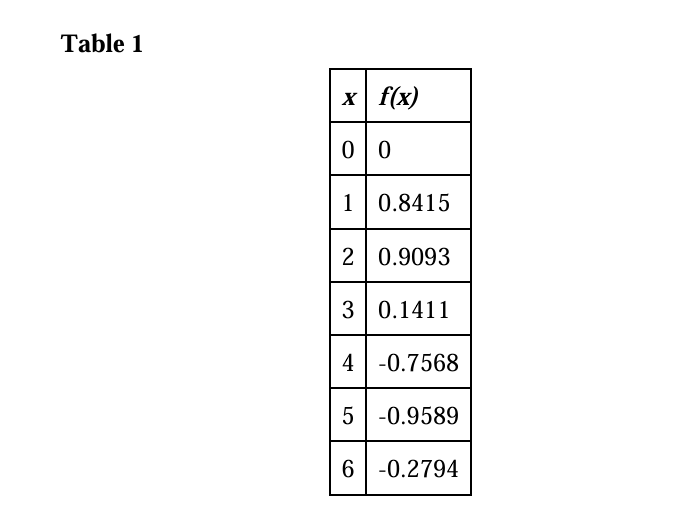

Soln:

Let us take some random values of x (here x = [2.5 3 3.5 4 4.5] is taken) and see the corresponding y values.

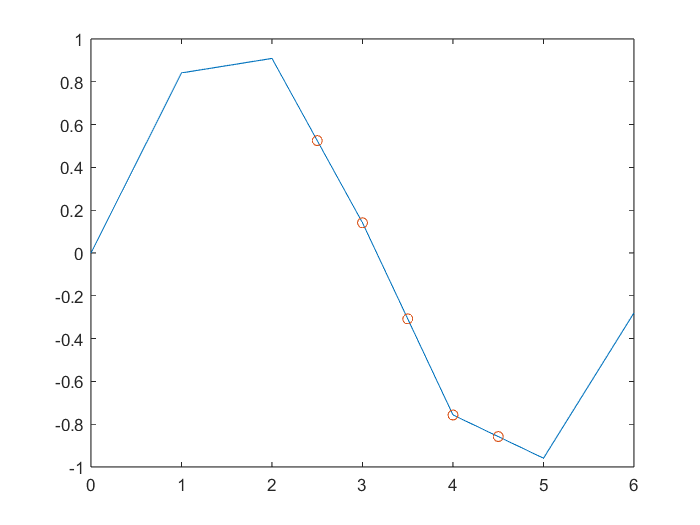

clc;
clear;
close all;

dataX = 0:6;
dataY = [0 0.8415 0.9093 0.1411 -0.7568 -0.9589 -0.2794];
n = length(dataX);

x = [2.5 3 3.5 4 4.5];

for i = 1:length(x)
    for j = 1:n-1
        if dataX(j)<=x(i) && dataX(j+1)>=x(i)
            x1 = dataX(j);
            x2 = dataX(j+1);
            y1 = dataY(j);
            y2 = dataY(j+1);
        end
    end
    y(i) = ((x(i)-x2)/(x1-x2))*y1 + ((x(i)-x1)/(x2-x1))*y2;         

end

plot(dataX, dataY)
hold on
plot(x,y,'o')

#### Exercise 3

 y = sin(x); x = 0:10; x(i) = 0:0.25:10;  Construct the interpolant y and plot. 

Soln:

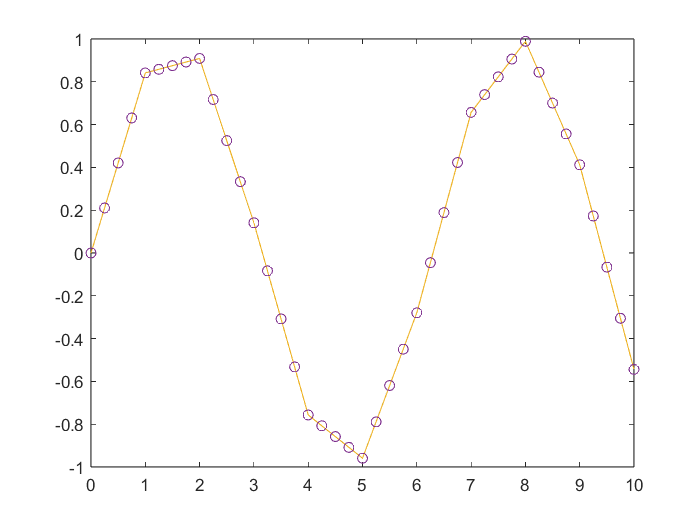

clc;
clear;
close all;

dataX = 0:10;           % x = 0:10
dataY = sin(dataX);    % y = sin(x)
n = length(dataX);

x = [0:0.25:10];    % x(i)

for i = 1:length(x)
    for j = 1:n-1
        if dataX(j)<=x(i) && dataX(j+1)>=x(i)
            x1 = dataX(j);
            x2 = dataX(j+1);
            y1 = dataY(j);
            y2 = dataY(j+1);
        end
    end
    y(i) = ((x(i)-x2)/(x1-x2))*y1 + ((x(i)-x1)/(x2-x1))*y2;         

end

plot(dataX, dataY)
hold on
plot(x,y,'o')

#### Exercise 4

Write a MATLAB program implementing Lagrange Polynomial.

Soln:

Let us take a random value of x, **x = 3.75** and find the corresponding y value using Lagrange Polynomial.

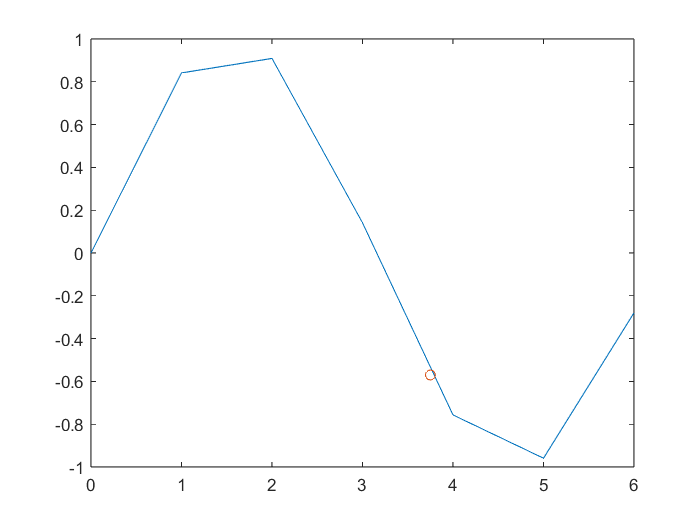

% LAGRANGE INTERPOLATION POLYNOMIAL
clc;
clear;
close all;

dataX = 0:6;
dataY = [0 0.8415 0.9093 0.1411 -0.7568 -0.9589 -0.2794];
n = length(dataX);

x = 3.75;

sum = 0;
for j = 1:n
    prod = 1;
    for k = 1:n
        if j ~= k
            prod = prod.*((x - dataX(k))/(dataX(j)-dataX(k)));
        end
    end
sum = sum + prod.*dataY(j);
end
y = sum;

plot(dataX, dataY)
hold on
plot(x, y, 'o')

#### Exercise 5

 Construct a Lagrange interpolating polynomials for the data points given in table 1. 

Soln:

Let us take some random values of x (here x = [2.5 3 3.5 4 4.5] is taken) and see the corresponding y values using lagrange polynomial interpolation.

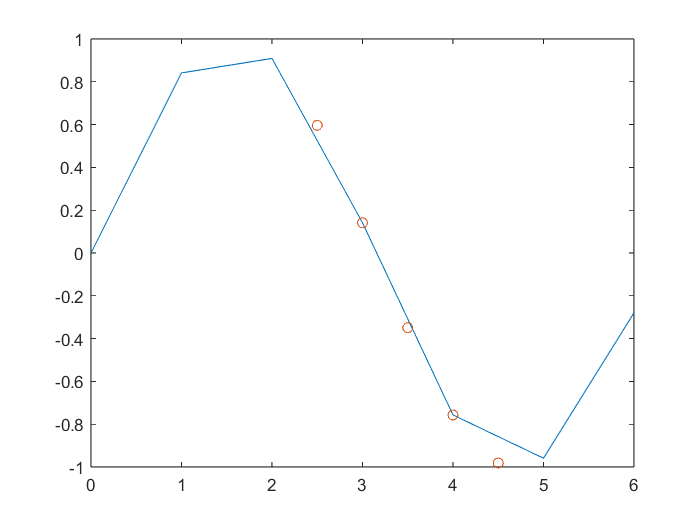

% LAGRANGE INTERPOLATION POLYNOMIAL
clc;
clear;
close all;

dataX = 0:6;
dataY = [0 0.8415 0.9093 0.1411 -0.7568 -0.9589 -0.2794];
n = length(dataX);

x = [2.5 3 3.5 4 4.5];
for i = 1:length(x)
    sum = 0;
    for j = 1:n
        prod = 1;
        for k = 1:n
            if j ~= k
                prod = prod.*((x(i) - dataX(k))/(dataX(j)-dataX(k)));
            end
        end
        sum = sum + prod.*dataY(j);
    end
    y(i) = sum;
end
plot(dataX, dataY)
hold on
plot(x, y, 'o')